data = load("Pomiary\zuzycie_pradu\pomiar_pradu_jeden_silnik.mat")

data = struct with fields:
    pwr_total: [0.3000 0.5000 0.4000 0.6000 0.3500 0.4200 0.3700 0.3500 0.4000 0.6000 0.4700 0.1700 0.3000 0.3000 0.4000 0.4200 0.4000 0.3500 0.4000 0.4000 0.2700 0.4000 0.5000 0.4500 0.4500 0.3500 0.3700 0.3700 0.3500 0.0500 0.3200 … ] (1×10050 double)


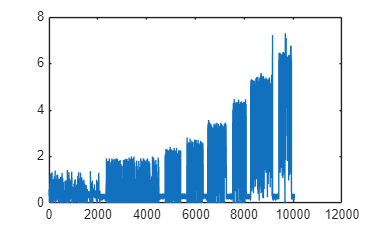

pwr_total = data.pwr_total;

plot(pwr_total)


fs = 50;        % częstotliwość próbkowania [Hz]
fc = 1;         % częstotliwość odcięcia filtru [Hz]

[b, a] = butter(2, fc/(fs/2), 'low');

[pwr_lotal_lp, d] = lowpass(pwr_total, fc/(fs/2), ImpulseResponse="iir");

pwr_fil = filtfilt(b, a, pwr_total);

t = 0.02:0.02:201

t =     0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800    1.0000


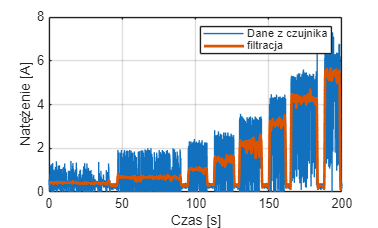


plot(t, pwr_total)
hold on
plot(t, pwr_fil, LineWidth=2)
hold off
grid on
xlabel("Czas [s]")
ylabel("Natężenie [A]")
legend("Dane z czujnika", "filtracja")
xlim([0 200])


avg_0 = mean(pwr_fil(4550:4750))

avg_0 = 0.3066

avg_5 = mean(pwr_fil(1:1500))

avg_5 = 0.4159

avg_10 = mean(pwr_fil(2600:4000))

avg_10 = 0.6525

avg_15 = mean(pwr_fil(5000:5350))

avg_15 = 1.0219

avg_20 = mean(pwr_fil(5750:6300))

avg_20 = 1.4529

avg_25 = mean(pwr_fil(6600:7200))

avg_25 = 2.1133

avg_30 = mean(pwr_fil(7650:8000))

avg_30 = 3.1612

avg_35 = mean(pwr_fil(8300:9000))

avg_35 = 4.2475

avg_40 = mean(pwr_fil(9500:9900))

avg_40 = 5.3419

data = load("Pomiary\zuzycie_pradu\pomiar_wszystkie_silniki_cut.mat")

data = struct with fields:
    amperage_total_10: [0.9000 0.5000 0.9500 1.5200 0.9200 0.8200 1 1.6200 0.8500 0.7700 1.4700 0.8500 0.7000 1.0200 1.2000 0.8500 0.6500 0.7200 0.6000 0.9000 0.7000 0.6200 0.8700 0.8000 1.2000 0.6700 0.7700 0.8500 0.8000 1.6200 0.6200 … ] (1×7350 double)


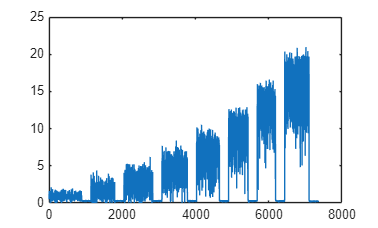

pwr_total = data.amperage_total_10;

plot(pwr_total)


fs = 50;        % częstotliwość próbkowania [Hz]
fc = 1;         % częstotliwość odcięcia filtru [Hz]

[b, a] = butter(2, fc/(fs/2), 'low');

[pwr_lotal_lp, d] = lowpass(pwr_total, fc/(fs/2), ImpulseResponse="iir");

pwr_fil = filtfilt(b, a, pwr_total);

t = 0.02:0.02:147

t =     0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800    1.0000


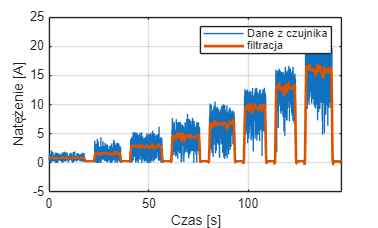


plot(t, pwr_total)
hold on
plot(t, pwr_fil, LineWidth=2)
hold off
grid on
xlabel("Czas [s]")
ylabel("Natężenie [A]")
legend("Dane z czujnika", "filtracja")
xlim([0 147])


avg_all_0 = mean(pwr_fil(930:1120))

avg_all_0 = 0.2882

avg_all_5 = mean(pwr_fil(1:1500))

avg_all_5 = 0.9322

avg_all_10 = mean(pwr_fil(1250:1700))

avg_all_10 = 1.5898

avg_all_15 = mean(pwr_fil(2100:2700))

avg_all_15 = 2.7910

avg_all_20 = mean(pwr_fil(3150:3700))

avg_all_20 = 4.4709

avg_all_25 = mean(pwr_fil(4150:4650))

avg_all_25 = 6.6585

avg_all_30 = mean(pwr_fil(5000:5400))

avg_all_30 = 9.4612

avg_all_35 = mean(pwr_fil(5800:6150))

avg_all_35 = 12.7686

avg_all_40 = mean(pwr_fil(6500:7000))

avg_all_40 = 15.8830

ster = [0, 5 10 15 20 25 30 35 40]

ster =      0     5    10    15    20    25    30    35    40


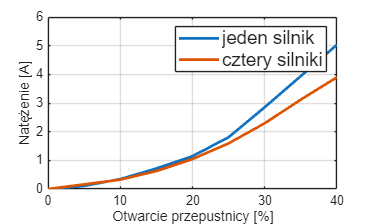


plot(ster, [avg_0, avg_5, avg_10 ...
    avg_15, avg_20, avg_25 ...
    avg_30, avg_35, avg_40] - avg_0, LineWidth=2)
hold on
plot(ster, ([avg_all_0, avg_all_5, avg_all_10 ...
    avg_all_15, avg_all_20, avg_all_25 ...
    avg_all_30, avg_all_35, avg_all_40] - avg_all_0) / 4, LineWidth=2)
hold off
grid on
xlabel("Otwarcie przepustnicy [%]")
ylabel("Natężenie [A]")
legend("jeden silnik", "cztery silniki", 'FontSize', 14)